# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.1 优雅的绘图颜色

#### 2.1.2 定制colormap

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

colormap 实际上也就是一组 n*3 的数组，每一行表示一个RGB向量（0-1 之间），因此，要定制 colormap 只需要得到这样一个数组即可。

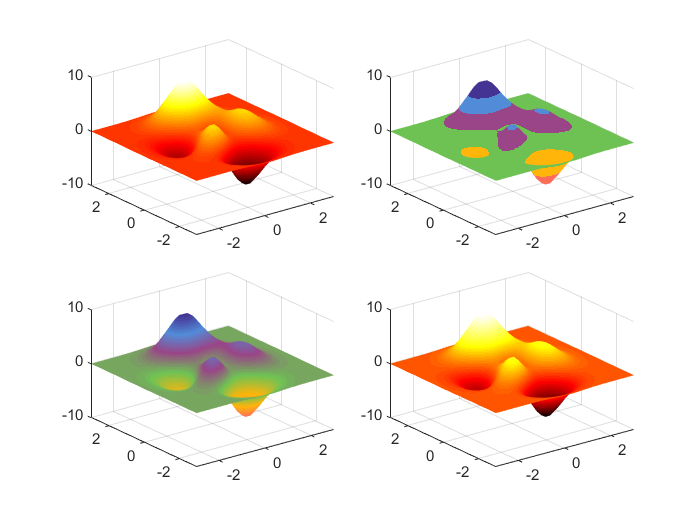

clear;clc;close all;
% 获取所有的颜色模板和颜色
[all_themes, all_colors] = GetColors();
% all_themes 的每个元素是一个 6*3 的数组，作为 colormap 似乎短了点，这样显示出来的效果就是突变
% 因此写了下面这个函数，对上面的数组插值，显示出渐变效果
map = GenColormap(all_themes{1}, 64);
tiledlayout(2, 2, 'TileSpacing', 'compact');
[x, y, z] = peaks(30);
plt1 = nexttile;
surf(x, y, z);
shading interp
plt2 = nexttile;
surf(x, y, z);
shading interp
plt3 = nexttile;
surf(x, y, z);
shading interp
plt4 = nexttile;
surf(x, y, z);
shading interp
% 单独设置每个子图的 colormap 否则就公用一个了
map_hot = hot(64);
set(plt1, 'Colormap', map_hot);
set(plt2, 'Colormap', all_themes{1});
set(plt3, 'Colormap', map);
% 黑 → 红 → 黄 → 白
colors = [0, 0, 0; 1, 0, 0; 1, 1, 0; 1, 1, 1];
set(plt4, 'Colormap', GenColormap(colors, 64));